clear all;
%  LOADING WORKSPACE VARIABLES
run('load_params_inertial_case.m');
load Lab_0_estimation/least_square_negative.mat;
load Lab_0_estimation/least_square_positive.mat;
%load Lab_0_estimation/tester_PID_Best.mat;
%load Lab_0_estimation/testerPIDBode.mat;
load Lab_0_estimation/least_square_acc.mat;

#### 
$$\bf{B_{eq}, \tau_{sf} \ ESTIMATION}$$
 

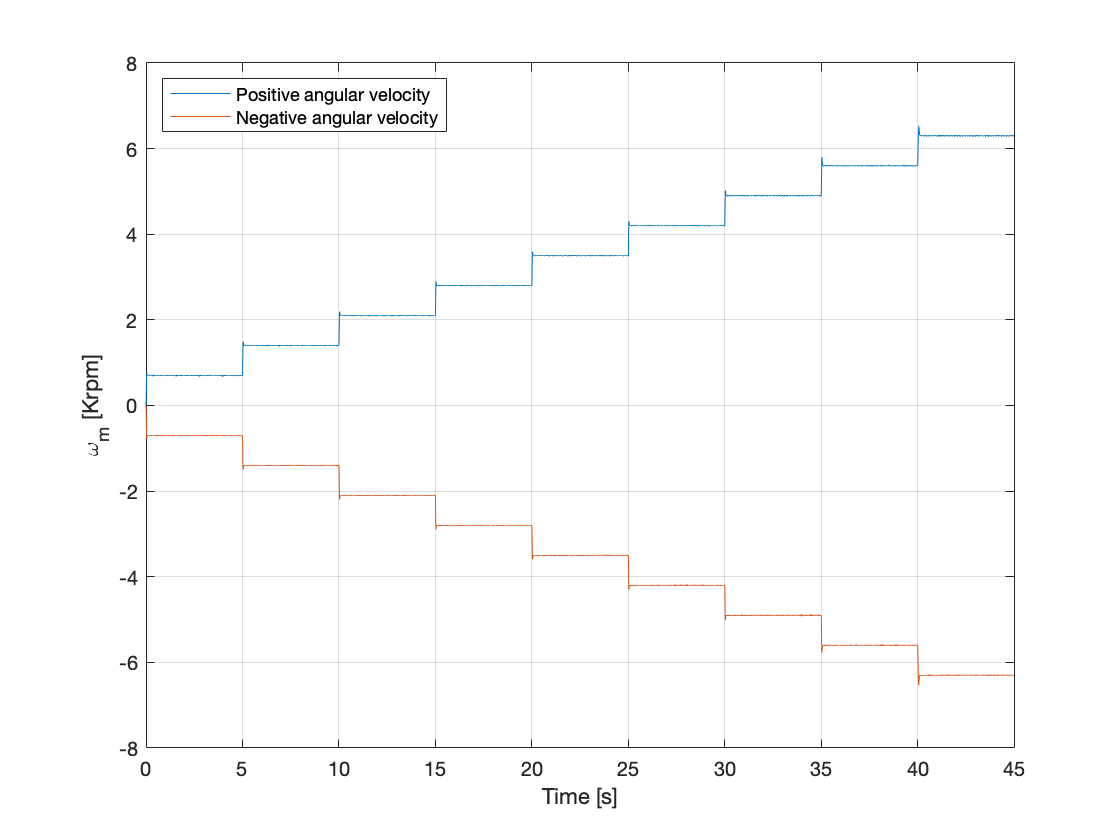

% w_m 

figure(1);

plot(wm_best_meas_pos.time(),wm_best_meas_pos.signals.values()*degs2rpm/1000);
xlabel('Time [s]'); ylabel('\omega_m [Krpm]');
grid on;
hold on;
plot(wm_best_meas_neg.time(),wm_best_meas_neg.signals.values()*degs2rpm/1000);
legend('Positive angular velocity','Negative angular velocity','location','northwest');
xlim([0,45]);

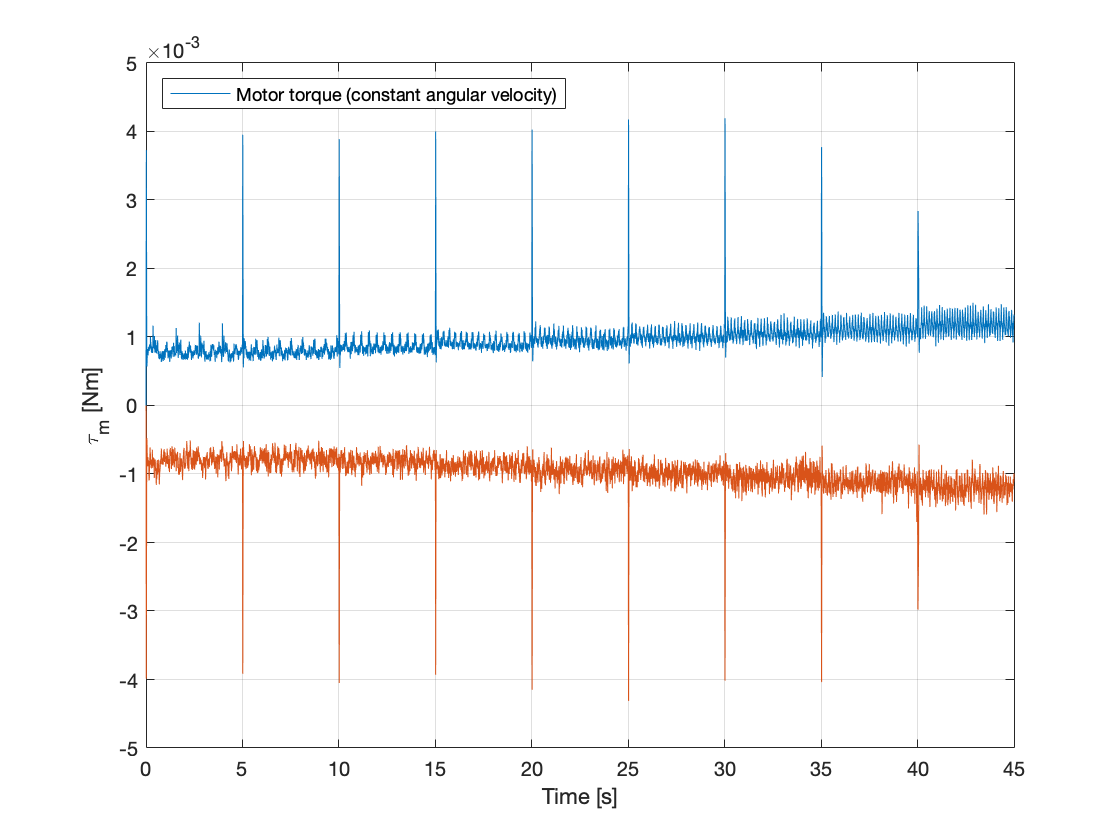

% torque_m

figure(2);

plot(torquem_best_pos.time(),torquem_best_pos.signals.values());
xlabel('Time [s]');
ylabel('\tau_m [Nm]');
grid on;
hold on;
plot(torquem_best_neg.time(),torquem_best_neg.signals.values());
legend('Motor torque (constant angular velocity)','location','northwest');

% Filtering w_m, torque_m

wm_neg_k = wm_best_meas_neg.signals.values*deg2rad;
wm_pos_k = wm_best_meas_pos.signals.values*deg2rad;
threshold = 0.05;
margin = 5;
new_t = [];
new_wm_pos_k = [];
new_wm_neg_k = [];
new_torque_best_pos = [];
new_torque_best_neg = [];
j = 1;
for t = 0:0.001:wm_best_meas_pos.time(length(wm_best_meas_pos.time))
   i = floor(t);
   modd = mod(i,margin);
   if (modd == 4 && (t < i+1 - threshold))
       new_wm_pos_k(j) = wm_pos_k(find(wm_best_meas_pos.time() == t));
       new_wm_neg_k(j) = wm_neg_k(find(wm_best_meas_neg.time() == t));
       new_torque_best_pos(j) = torquem_best_pos.signals.values(find(torquem_best_pos.time() == t));
       new_torque_best_neg(j) = torquem_best_neg.signals.values(find(torquem_best_neg.time() == t));
       new_t(j) = t;
       j = j + 1;
   end
   if (modd == 0 && (t > i + threshold))
       new_wm_pos_k(j) = wm_pos_k(find(wm_best_meas_pos.time() == t));
       new_wm_neg_k(j) = wm_neg_k(find(wm_best_meas_neg.time() == t));
       new_torque_best_pos(j) = torquem_best_pos.signals.values(find(torquem_best_pos.time() == t));
       new_torque_best_neg(j) = torquem_best_neg.signals.values(find(torquem_best_neg.time() == t));
       new_t(j) = t;
       j = j + 1;
   end
   if (modd == 1 || modd == 2 || modd == 3)
       new_wm_pos_k(j) = wm_pos_k(find(wm_best_meas_pos.time() == t));
       new_wm_neg_k(j) = wm_neg_k(find(wm_best_meas_neg.time() == t));
       new_torque_best_pos(j) = torquem_best_pos.signals.values(find(torquem_best_pos.time() == t));
       new_torque_best_neg(j) = torquem_best_neg.signals.values(find(torquem_best_neg.time() == t));
       new_t(j) = t;
       j = j + 1;
   end
end

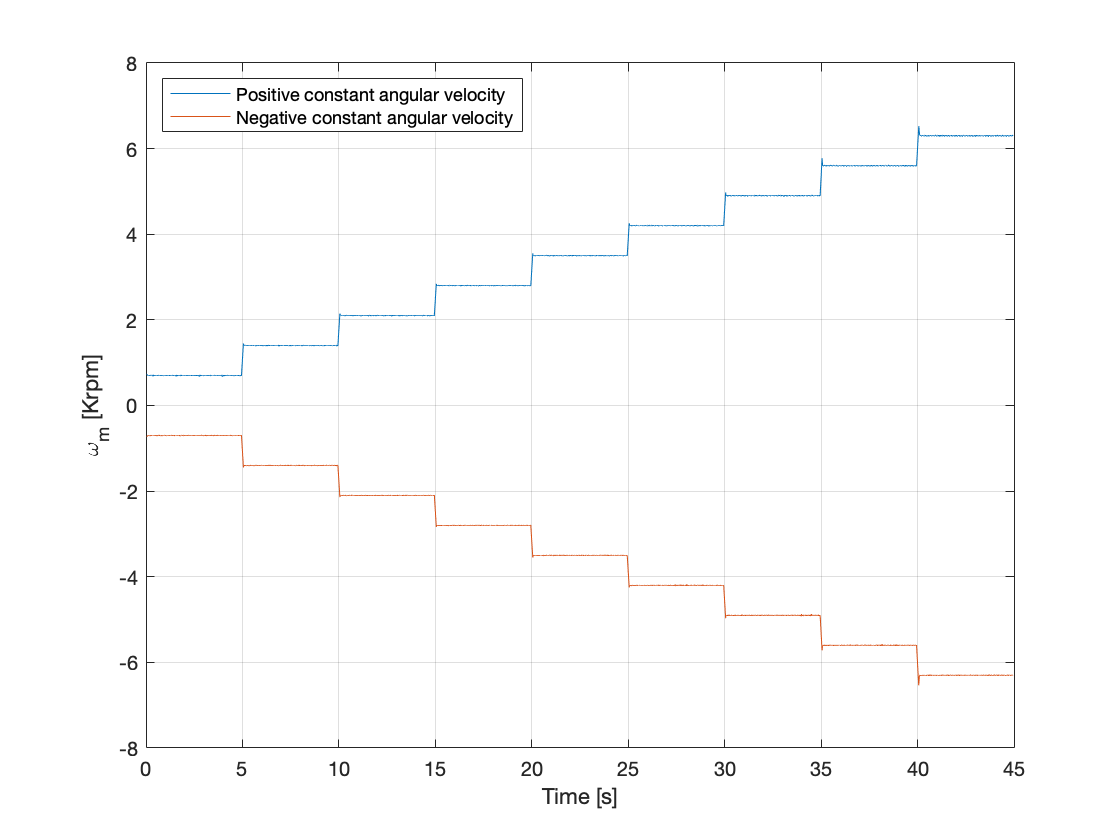

% Filtered w_m

figure(3);

plot(new_t,transpose(new_wm_pos_k)*rads2rpm/1000);
xlabel('Time [s]'); 
ylabel('\omega_m [Krpm]');
hold on;
plot(new_t,transpose(new_wm_neg_k)*rads2rpm/1000);
legend('Positive constant angular velocity','Negative constant angular velocity','location','northwest');
grid on;

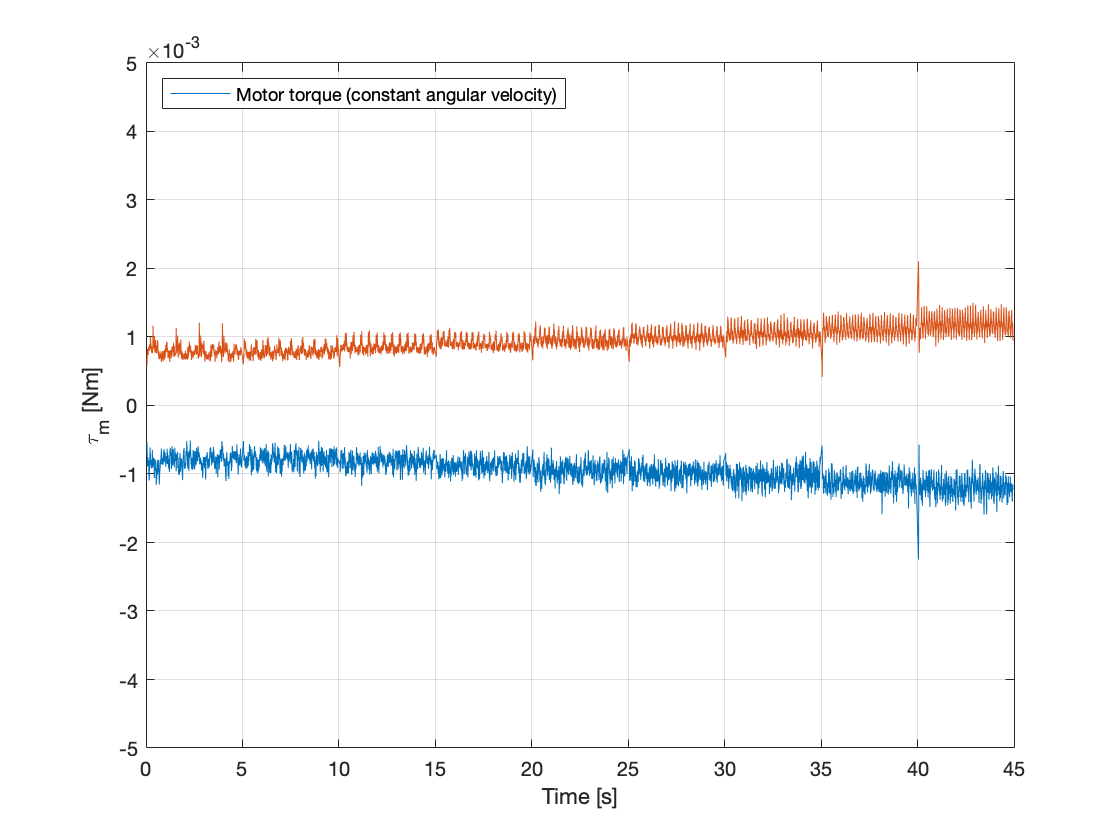

% Filtered torque_m

figure(4);

plot(new_t,transpose(new_torque_best_neg));
hold on;
grid on;
plot(new_t,transpose(new_torque_best_pos));
xlabel('Time [s]');
ylabel('\tau_m [Nm]');
legend('Motor torque (constant angular velocity)','location','northwest');
ylim([-5e-3,5e-3]);

#### 
$$\bf{Estimation} \  \bf{ parameters \ (Filtered)} \ B_{eq}, \tau_{sf}$$


Y = [transpose(new_torque_best_neg);transpose(new_torque_best_pos)];
col_1 = [transpose(new_wm_neg_k);transpose(new_wm_pos_k)];
col_2 = [sign(transpose(new_wm_neg_k))/14;sign(transpose(new_wm_pos_k))/14];
Phy = [col_1 col_2];
theta_filt = inv(transpose(Phy)*Phy)*transpose(Phy)*Y;
fprintf('Estimation parameters: \n \n  B_eq = %d.\n tau_sf = %d', theta_filt(1), theta_filt(2));

Estimation parameters: 
 
  B_eq = 7.040304e-07.
 tau_sf = 9.787708e-03

#### 
$$\bf{Estimation} \  \bf{ parameters \ (Not \ Filtered)} \ B_{eq}, \tau_{sf}$$


Y = [torquem_best_neg.signals(1).values;torquem_best_pos.signals.values];
col_1 = [wm_neg_k;wm_pos_k];
col_2 = [sign(wm_neg_k)/14;sign(wm_pos_k)/14];
Phy = [col_1 col_2];
theta = inv(transpose(Phy)*Phy)*transpose(Phy)*Y;
fprintf('Estimation parameters: \n \n  B_eq = %d.\n tau_sf = %d', theta(1), theta(2));

Estimation parameters: 
 
  B_eq = 6.964057e-07.
 tau_sf = 9.990072e-03

#### 
$$\bf{J_{eq} \ ESTIMATION}$$
 

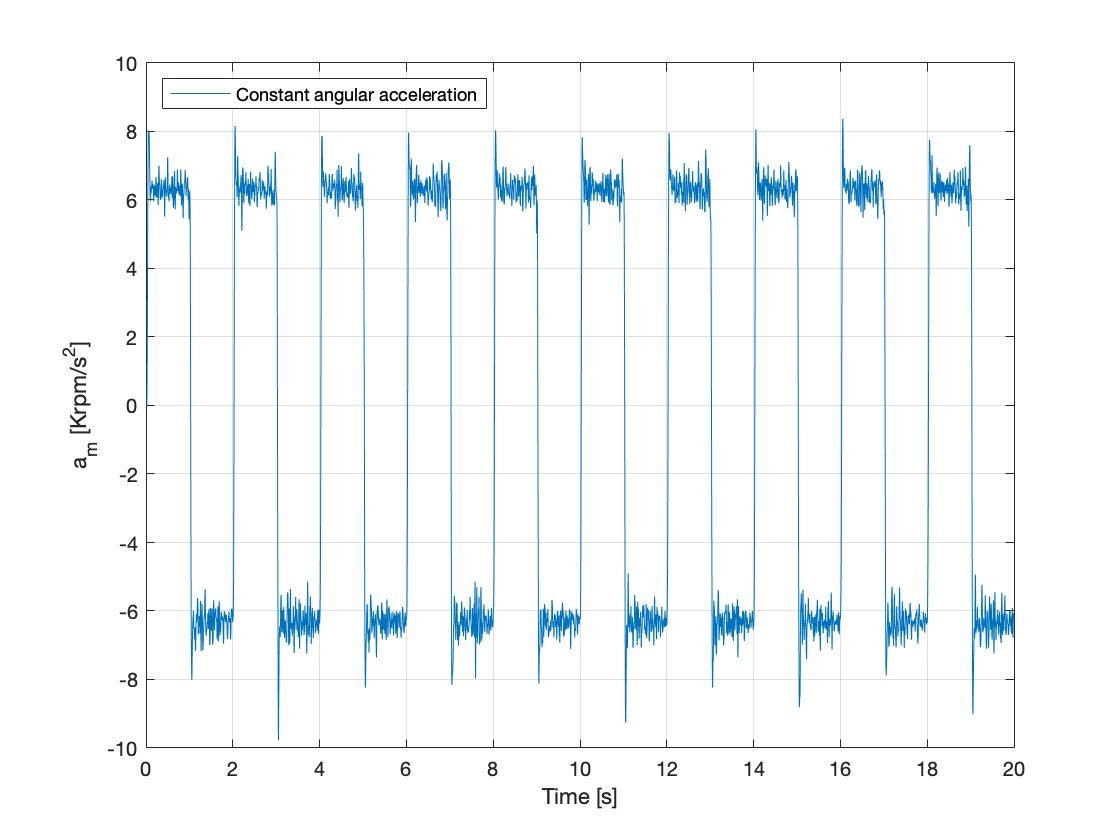

% a_m

am_best_meas = am_best_meas * deg2rad;

figure(5);

plot(al_best_meas.time(),am_best_meas*rads2rpm/1000);
xlabel('Time [s]'); 
ylabel('a_m [Krpm/s^2]');
grid on;
xlim([0,20]);
legend('Constant angular acceleration','location','northwest');

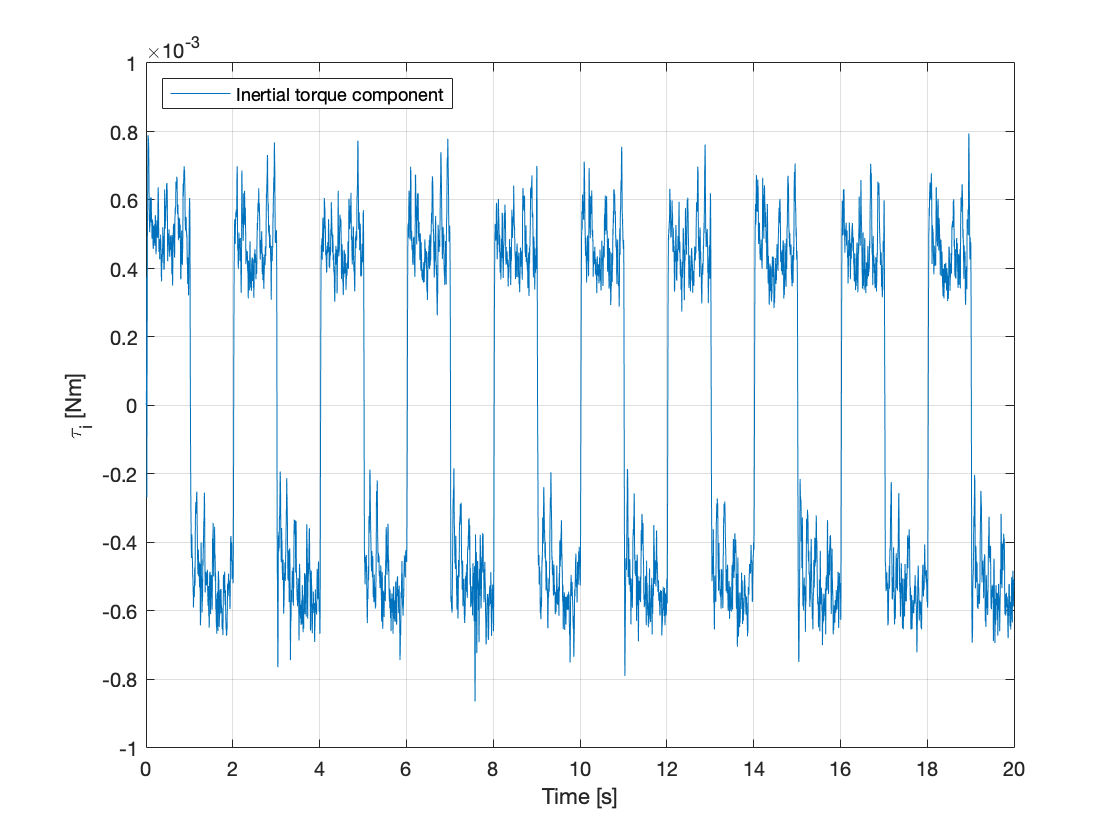

% torque_i 

wm_best_meas = wl_best_meas.signals.values * gbox.N * deg2rad;
torque_i = torquem_best.signals.values() - (theta(1) * wm_best_meas + theta(2) * sign(wm_best_meas) / gbox.N);

figure(6);

plot(torquem_best.time(),torque_i);
xlabel('Time [s]');
ylabel('\tau_i [Nm]');
ylim([-1e-3,1e-3]);
grid on;
hold on;
legend('Inertial torque component','location','northwest');

% Filtering a_m, torque_i

new_am_best_meas = [];
new_torque_i = [];
new_am_t = [];
threshold = 0.05;
j = 1;
for t = 0:0.001:al_best_meas.time(length(al_best_meas.time()))
   i = floor(t);
   if (t >= i + threshold && t < (i+(i+1))/2)
       new_am_best_meas(j) = am_best_meas(find(al_best_meas.time() == t));
       new_torque_i(j) = torque_i((find(torquem_best.time() == t)));
       new_am_t(j) = t;
       j = j + 1;
   end
   if (t < i+1 - threshold && t > (i+(i+1))/2)
       new_am_best_meas(j) = am_best_meas(find(al_best_meas.time() == t));
       new_torque_i(j) = torque_i((find(torquem_best.time() == t)));
       new_am_t(j) = t;
       j = j + 1;
   end
end

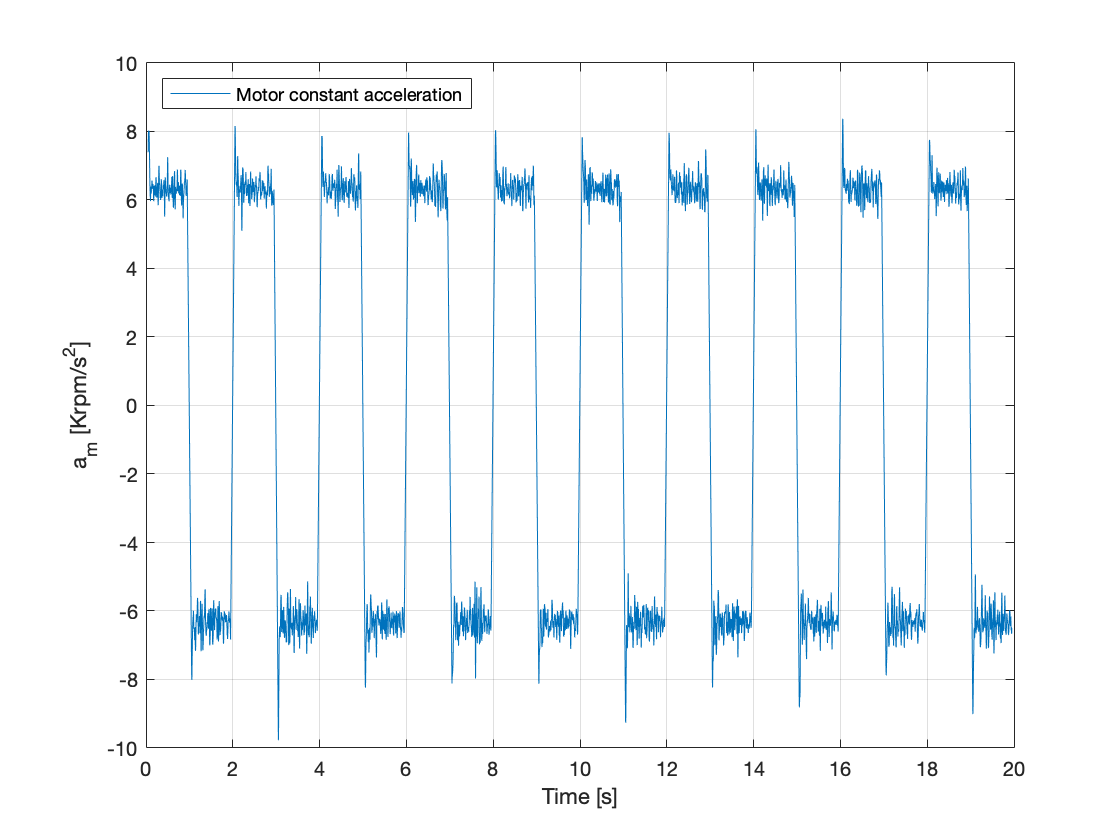

% Filtered a_m

figure(7);

plot(new_am_t,new_am_best_meas*rads2rpm/1000);
xlabel('Time [s]'); 
ylabel('a_m [Krpm/s^2]');
grid on;
xlim([0,20]);
legend('Motor constant acceleration','location','northwest');

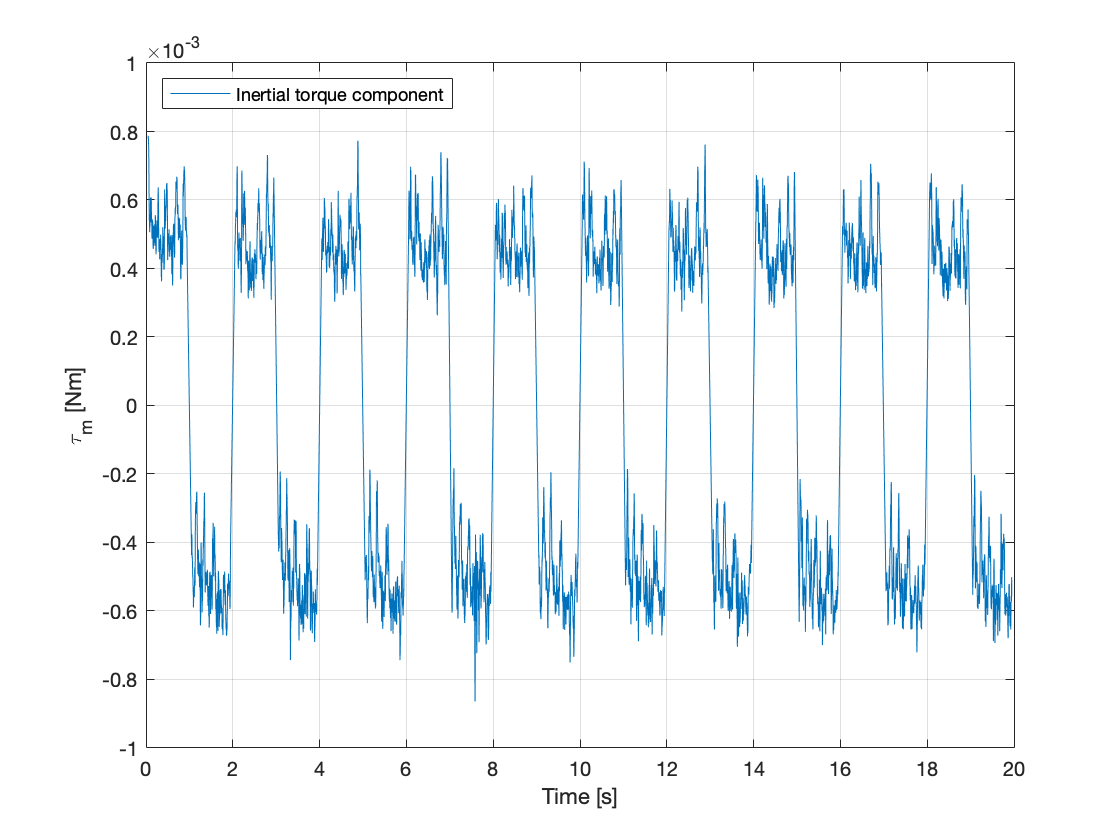

% Filtered torque_i

figure(8); 

plot(new_am_t,new_torque_i);
xlabel('Time [s]');
ylabel('\tau_m [Nm]');
ylim([-1e-3,1e-3]);
grid on;
hold on;
legend('Inertial torque component','location','northwest');

% a_m, torque_i (pos/neg)

am_best_meas_pos = [];
am_best_meas_neg = [];
torque_i_pos = [];
torque_i_neg = [];
am_pos_time = [];
am_neg_time = [];
j_pos = 1;
j_neg = 1;
for t = 0:0.001:new_am_t(length(new_am_t))
   if (new_am_best_meas(find(new_am_t == t)) > 0)
       am_best_meas_pos(j_pos) = new_am_best_meas(find(new_am_t == t));
       torque_i_pos(j_pos) = new_torque_i(find(new_am_t == t));
       am_pos_time(j_pos) = t;
       j_pos = j_pos + 1;
   end 
   if (new_am_best_meas(find(new_am_t == t)) < 0)
       am_best_meas_neg(j_neg) = new_am_best_meas(find(new_am_t == t));
       torque_i_neg(j_neg) = new_torque_i(find(new_am_t == t));
       am_neg_time(j_neg) = t;
       j_neg = j_neg + 1;
   end 
end

#### 
$$\bf{Estimation} \  \bf{ parameter} \ J_{eq}$$


am_best_meas_pos = transpose(am_best_meas_pos);
am_best_meas_neg = transpose(am_best_meas_neg);
torque_i_pos = transpose(torque_i_pos);
torque_i_neg = transpose(torque_i_neg);
sum = 0;
for index = 1:1:length(am_pos_time)
    sum = sum + (torque_i_pos(index) - torque_i_neg(index))/(am_best_meas_pos(index) - am_best_meas_neg(index));
end
J_eq = sum / length(torque_i_neg);
fprintf('Estimation parameter: \n \n  J_eq = %d.', J_eq);

Estimation parameter: 
 
  J_eq = 7.411006e-07.

#### 
$$\bf{LEAST \ SQUARE\ APPROACH \  $($ \bf{B_{eq},\ \tau_{sf},\ J_{eq}} $)$ }$$


Y_tot= [torquem_best.signals.values];
col_1_tot = [am_best_meas];
col_2_tot = [wl_best_meas.signals.values*14*deg2rad];
col_3_tot = [sign(wl_best_meas.signals.values*14*deg2rad)/14];
Phy_tot = [col_1_tot col_2_tot col_3_tot];
theta_tot = inv(transpose(Phy_tot)*Phy_tot)*transpose(Phy_tot)*Y_tot;
fprintf('Estimation parameters: \n \n  J_eq = %d.\n B_eq = %d \n tau_sf %d', theta_tot(1), theta_tot(2), theta_tot(3));

Estimation parameters: 
 
  J_eq = 7.340180e-07.
 B_eq = 7.494051e-07 
 tau_sf 9.486994e-03